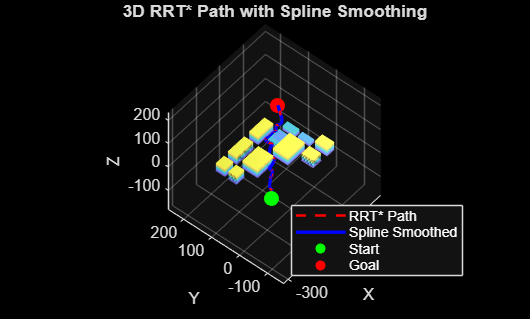

clc; clear; close all;

%% Load maps and data
load data/UrbanScenario_3D.mat      % occMap3D
load data/UrbanScenario.mat         % bboxes

%% Define sampling bounds
xmin = min(bboxes(:,1));% Western-most edge of the map
ymin = min(bboxes(:,2));% Southern-most edge of the map
xmax = max(bboxes(:,4));% Eastern-most edge
ymax = max(bboxes(:,5));% Northern-most edge
zmax = max(bboxes(:,6));% height of the tallest building

zSafe = zmax + 5;

%% Find free START and GOAL using checkOccupancy
step = 2;
[xg,yg] = meshgrid(xmin:step:xmax, ymin:step:ymax);
zg = zSafe * ones(size(xg)); %invisible ceiling
pts = [xg(:) yg(:) zg(:)];

occ = checkOccupancy(occMap3D, pts);
freePts = pts(occ==0,:);
assert(~isempty(freePts),'No free space found');

startPos = freePts(1,:);
% We find longest distance for setting goal
d = vecnorm(freePts - startPos,2,2);% (euclidian norm,horizontal)
[~,i] = max(d);
goalPos = freePts(i,:);

%% State space (SE3)
ss = stateSpaceSE3; %Special Euclidean Group 3
ss.StateBounds = [xmin xmax; ymin ymax; 0 zSafe+5; -1 1; -1 1; -1 1; -1 1];%Boundaries for drone movement

sv = validatorOccupancyMap3D(ss);
sv.Map = occMap3D;
sv.ValidationDistance = 1.0;

%% RRT* planner
planner = plannerRRTStar(ss, sv);
planner.MaxIterations = 3000;
planner.MaxConnectionDistance = 15;

startState = [startPos 1 0 0 0];
goalState  = [goalPos  1 0 0 0];

[pathObj, solnInfo] = plan(planner, startState, goalState);
assert(~isempty(pathObj.States),'RRT* failed');

pathXYZ = pathObj.States(:,1:3);

%% Spline smoothing (3D)
d = sqrt(sum(diff(pathXYZ).^2,2)); % Pythagorean theorem
s = [0; cumsum(d)]; % Cumulative Sum of points distance travelled

% Cubic Spline Interpolation
ppX = spline(s, pathXYZ(:,1));
ppY = spline(s, pathXYZ(:,2));
ppZ = spline(s, pathXYZ(:,3));

N = 300;
sFine = linspace(0,s(end),N); % To have list of distances
xs = ppval(ppX,sFine); % Piecewise Polynomial Evaluation
ys = ppval(ppY,sFine);
zs = ppval(ppZ,sFine);

pathXYZ_smooth = [xs' ys' zs'];

%% Visualization
figure('Color','k');
hold on;
grid on; 
axis equal;
show(occMap3D);

h1 = plot3(pathXYZ(:,1),pathXYZ(:,2),pathXYZ(:,3),'r--','LineWidth',1.5);
h2 = plot3(xs,ys,zs,'b','LineWidth',2);
h3 = scatter3(startPos(1),startPos(2),startPos(3),80,'g','filled');
h4 = scatter3(goalPos(1),goalPos(2),goalPos(3),80,'r','filled');

xlabel('X'); ylabel('Y'); zlabel('Z');
title('3D RRT* Path with Spline Smoothing');

legend([h1 h2 h3 h4], ...
       {'RRT* Path','Spline Smoothed','Start','Goal'}, ...
       'TextColor','w','Location','best');


%% Save 
save data/globalPath3D.mat ...
     pathXYZ pathXYZ_smooth startPos goalPos

disp('Saved: data/globalPath3D.mat');

Saved: data/globalPath3D.mat
